**PCS 130 Lab 4 Standing Waves**

In this lab we will be looking at the formation of standing waves on a string. You are tasked with determining the physical characteristics of the string (linear density) and compare it experimentally using the theory being waves and also by measuring it directly.

- Perform error analysis and error propagation

- Type A: Estimate the error using statistics.

- Type B: Estimate the error using scientific judgement.

**Standing Wave Data**

As done in previous labs, create arrays that will hold your data in order to be analysed. Be mindful of how you organize your data if inputting it manually! Remember, you want each element in the array to be matched up correctly with the tension and number of antinodes it has. This means that the order you enter your elements into the array matters.

%Declare known constants
g = 9.8; % Replace dummy with acceleration due to gravity
m = [0.1 0.1 0.1 0.1 0.1 0.2 0.2 0.2 0.2 0.2 0.3 0.3 0.3 0.3 0.3]'; % hanging mass
T = m.*g; % Tension force
L = 1.304; %Replace dummy with the length of the string for the oscillator
n = [1 2 3 4 5 1 2 3 4 5 1 2 3 4 5]'; % number of antinodes in the standing wave
fn =[15.0 29.3 44.0 67.0 74.9 20.5 42.7 63.3 81.2 106 25.7 46.9 77.4 102 130]';% frequency for a given n and tension

%Declare x and y variables which you will use to plot.
x = 4*L.^2./n.^2 * 1./T %Replace dummy with the correct x values. What combination of variables would you choose/calculate as the x-values for your plot in order for it to be linear?

x =     6.9405
    1.7351
    0.7712
    0.4338
    0.2776
    3.4702
    0.8676
    0.3856
    0.2169
    0.1388
    2.3135
    0.5784
    0.2571
    0.1446
    0.0925


y = 1./fn.^2 %Replace dummy with the correct y values. What combination of variables would you choose/calculate as the y-values for your plot in order for it to be linear?

y =     0.0044
    0.0012
    0.0005
    0.0002
    0.0002
    0.0024
    0.0005
    0.0002
    0.0002
    0.0001
    0.0015
    0.0005
    0.0002
    0.0001
    0.0001


**Importing data into matlab **

***(Skip this section if you did not organize your data via a spreadsheet)***

In order to read in the file into matlab as a table from a .csv, you will need to get the 'path' of the file. The path identifies where in the computer your file is stored. 

To get the path on the lab Mac follow the steps below.

- On the Mac, click the finder icon in the dock to open a Finder window.

- Navigate to where you downloaded the file. It is likely in the downloads folder.

- Choose View > Show Path Bar, or press the Option key to show the path bar momentarily. The location and nested folders that contain your file or folder are displayed near the bottom of the Finder window.

- Right click the bar on the bottom of the finder window and copy.

Once you have copied the path, paste the string into the brackets of the readtable function below. Since it is a string, make sure that it is in quotations.

% Import the data. Uncomment the line below and insert the path into the
% readtable function.
% data_table = readtable('Paste the path to the file here'); 

**Type A evaluation of Uncertainty and plotting.**

You will need to create a linear plot of your data in order to determine the linear density of the string. Using the x and y values from the previous section, plot them so that it results in a linear graph using the linear model function. Once you create your plot, to qestimate the uncertainty statitically you will need to look at the **standard error** of the slope. Be critical of what this slope represents based on what you plotted! You may need to propagate the uncertainty further to account for constants! Be sure to properly label your plot as well.

For the purposes of this lab we will utilize the fitlm() function from the statistics and machine learning toolbox from the first lab to both fit and characterize the error.

standing_wave_model = fitlm(x,y)

standing_wave_model = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)    1.1038e-05    1.5183e-05    0.72697       0.48013
    x1             0.00064813     6.987e-06     92.763    9.9411e-20


Number of observations: 15, Error degrees of freedom: 13
Root Mean Squared Error: 4.83e-05
R-squared: 0.998,  Adjusted R-Squared: 0.998
F-statistic vs. constant model: 8.6e+03, p-value = 9.94e-20

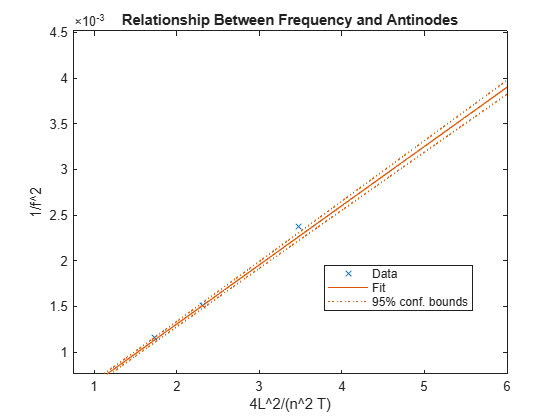

plot(standing_wave_model);

title('Relationship Between Frequency and Antinodes')
ylabel('1/f^2') %y-axis label. 
xlabel('4L^2/(n^2 T)') %x-axis label. 

**Type B evaluation of Uncertainty**

A type B evaluation of uncertainty will require you to use your scientific judgment. Think about how the experiment was performed and which ways error may be introduce when you collect your measurements. Some general examples are when you measure the length of the reference string and its mass. What can you say about the resolution of the meter stick you use (and the spacing between the lines) or the scale to measure the mass? You may need to add in additional uncertainties based on your specific procedure and data collected.

%Example uncertainties - taking into account the resolution of the
%measurement device for your Length and Mass measurements when referencing
%the string. There could be more uncertainties you want to take into
%account.
L = 1.783 % 1.78308

L = 1.7830

M_s = 0.0016 % 0.001673

M_s = 0.0016

mu = M_s / L

mu = 8.9736e-04

dL = 0.001 % Replace dummy with the uncertainty in the measured length of the reference string.

dL = 1.0000e-03


dM_s = 0.0001 % Replace dummy with the uncertainty in the measured mass of the string.

dM_s = 1.0000e-04

dmu = mu * sqrt((dM_s / M_s)^2 + (dL / L)^2)

dmu = 5.6088e-05

**Propagation of Uncertainty**

It is likely that you will need to propagate the uncertainty of your individual variables for at least one method. The code block below is provided to help with your calculations with example calculations of error propagation from the lab manual. Manipulate or change the equations you need below to estimate the uncertainty of your experiment. Note, you may not need to use all the equations.

% % Example Calculation of multiplying constants Replace dA or dB with
% % the actual uncertainty
% C_con = abs(b)*dA
% % Example Calculation for addition and subtraction. Replace dA or dB with
% % the actual uncertainty
% C_as = (dA^2 + dB^2)^(1/2)
% % Example Calculation for multiplication and division. Replace dA or dB with
% % the actual uncertainty
C_md = M_s/L*((dM_s/M_s)^2 + (dL/L)^2)^(1/2) % C_md = dC*((dA/A)^2 + (dB/B)^2)^(1/2)

C_md = 5.6088e-05